# **Example1_GoodServe**

## **purpose**

## **description**

## **references**

based on a model described in Danby, J. M. A. (1997) Computer Modeling: From Sports to Spaceflight ... From Order To Chaos, Willmann-Bell, Inc., Richmond, VA., p. 159.

## **joke of the day**

Q: What's an 'Open Set'? A: Something that Pete Sampras usually wins at Forrest Hills

## **create object**

myServe = TennisServe();

## **user inputs**

initial position of server

myServe.x0 = -38.5; % (ft)
myServe.y0 = 10;    % (ft)
myServe.z0 = 8;     % (ft)
% initial velocity and spin of ball
myServe.v0 = 140.0; % (ft/s) speed
myServe.phi0 = -20; % (deg) angle of ball flight with respect to x-axis
myServe.theta0 = -3.2; % (deg) elevation angle of intial ball flight
myServe.spin_x =-20.0;  % (rad/s)  
myServe.spin_y = 75.0; % (rad/s) applying a top spin
myServe.spin_z = 0.0;  % (rad/s)  
% drag considerations
myServe.C_D = 0.4;
myServe.C_L = 0.107;
myServe.grip_factor = 1;

## **run the model**

[trajTable] = myServe.getTrajectory();

Start Pos=[-38.500000,10.000000,8.000000] ft Vel=[131.351839,-47.808159,-7.815011] ft/s


## **visualize the model results**

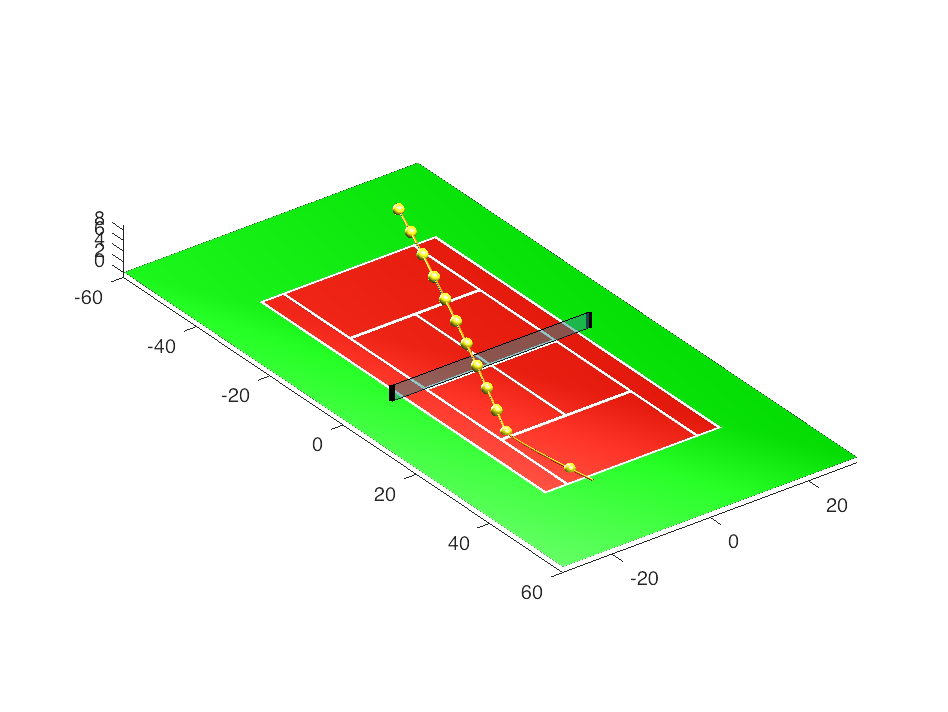

plot3(trajTable.x,trajTable.y,trajTable.z); 
hold on;

% spaghetti of the path of the ball
np = length(trajTable.x);
colorCode = [1 0.5 0];
C = [ones(np,1)' zeros(np,1)' zeros(np,1)'];
width = 0.4*ones(np,1);
n = 20;
verts = [trajTable.x trajTable.y trajTable.z];
[vx,vy,vz]=spaghetti_XYZ(verts,width,n);
s = surf(vx,vy,vz, 'FaceColor', colorCode, 'EdgeColor', 'none');
hold on; 

% draw the court base
courtMap = imread('TennisCourtMap.jpg');
court = surf([-60 60],[-30 30],zeros(2,2));
court.CData = courtMap;
court.FaceColor = 'texturemap'; 
court.EdgeColor = 'none'; 

% draw the net
netX = [0 0 0 0];
netY = [-20 -20 20 20];
netZ = [0.05 3 3 0.05];
fill3(netX,netY,netZ,[0.25 0.75 0.75],'facealpha',0.5);
plot3([0 0],[-20 -20],[0 3],'k','linewidth',3);
plot3([0 0],[20 20],[0 3],'k','linewidth',3);

% draw a ball at select locations along the path
ballMap = imread('TennisBallMap.png');
[xp,yp,zp] = sphere(60);
for iball = 1:floor(np/10):np
    s = surf(xp+trajTable.x(iball),yp+trajTable.y(iball),zp+trajTable.z(iball));
    s.CData = ballMap;
    s.FaceColor = 'texturemap';
    s.EdgeColor = 'none';
end

% add lights
camlight('left');
light('Position',[0 0 100],'Style','local');
light;
lighting phong;

% change the view
axis equal;
view([53.3 30]);